clear all;
i1 = @(t) (2 * 96485 * 1 * 0.4 * 1/180 * 1/1000 * (6.6 * 10.^(-6)).^(1/2))./(3.14159*t).^(1/2)

i1 = function_handle with value:
    @(t)(2*96485*1*0.4*1/180*1/1000*(6.6*10.^(-6)).^(1/2))./(3.14159*t).^(1/2)


i2 = @(t) (2 * 96485 * 1 * 4 * 1/180 * 1/1000 * (6.6 * 10.^(-6)).^(1/2))./(3.14159*t).^(1/2)

i2 = function_handle with value:
    @(t)(2*96485*1*4*1/180*1/1000*(6.6*10.^(-6)).^(1/2))./(3.14159*t).^(1/2)


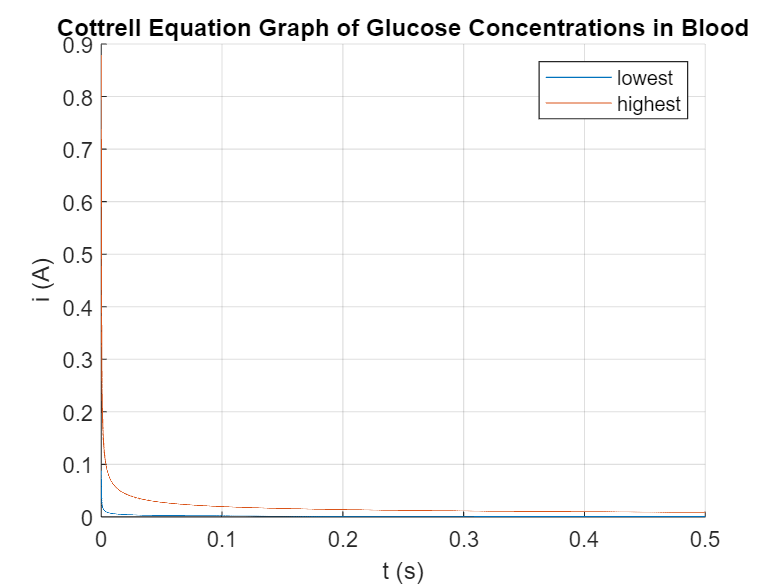

x = linspace(0, 0.5, 10000);
y1 = i1(x);
y2 = i2(x);
figure;
hold on;
plot(x, y1);
plot(x, y2);
xlabel('t (s)');
ylabel('i (A)');
legend('lowest','highest')
title('Cottrell Equation Graph of Glucose Concentrations in Blood');
grid on;